test script for violin/ dabest plot

Try to set up violin plot settings so looks like pretty dabest python

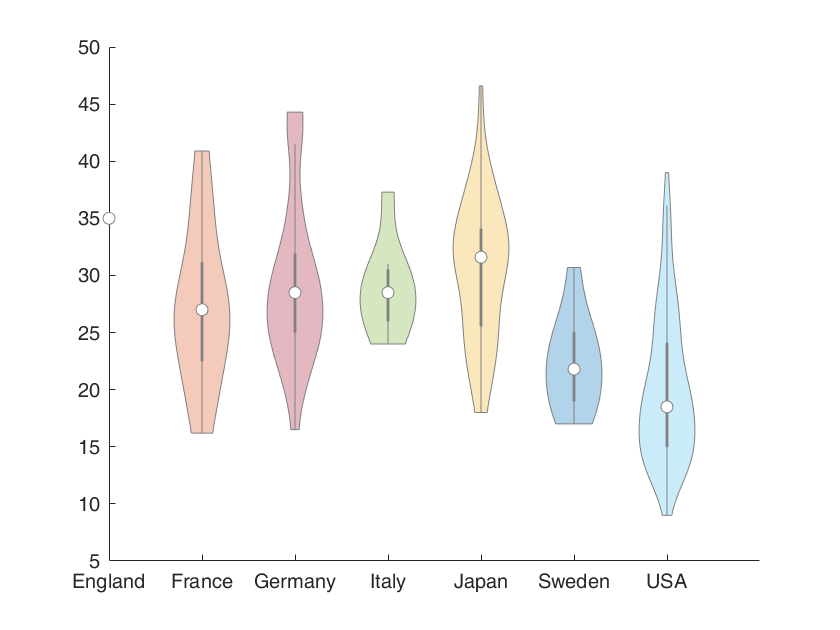

load carbig MPG Origin
Origin = cellstr(Origin);
figure
vs = violinplot(MPG, Origin, 'ShowData',false);

delta_name_plot = 1×1 cell array
    {' '}


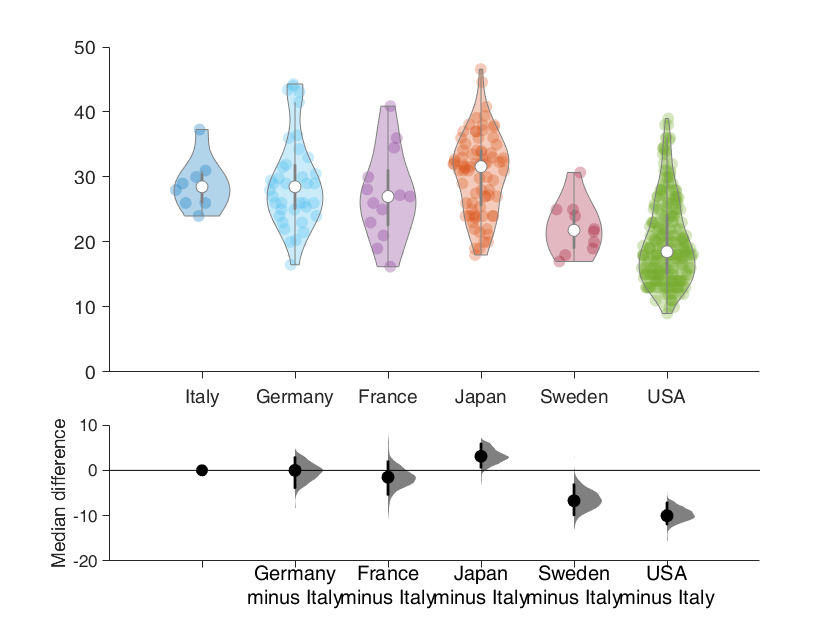

stats1 = 11×4 table
            Group            Value         CIs           N 
    _____________________    _____    ______________    ___

    'Italy'                  28.5        26       31      8
    'Germany'                28.5        26       30     39
    'France'                   27        23     31.3     14
    'Japan'                  31.6      29.5     32.4     79
    'Sweden'                 21.8        19       25     11
    'USA'                    18.5        18     19.4    254
    'Germany minus Italy'       0      -4.5        3    NaN
    'France minus Italy'     -1.5        -7        3    NaN
    'Japan minus Italy'       3.1         0        6    NaN
    'Sweden minus Italy'     -6.7     -10.5       -2    NaN
    'USA minus Italy'         -10     -12.9       -7    NaN


h = struct with fields:
    fig: [1×1 Figure]
    ax1: [1×1 Axes]
     v1: [1×6 Violin]
    ax2: [1×1 Axes]
     v2: [1×6 DabestViolin]



%dabest freaks out at empty args
Origin2= Origin;
MPG2 = MPG;
Origin2(strcmp(Origin,'England'))=[];
MPG2(strcmp(Origin,'England'))=[];
figure
%grouporder specifies what everything is referenced against so important
grouporder={'Italy','Germany','France','Japan','Sweden', 'USA'};
[stats1 h]=violinplusdabest(MPG2, Origin2,grouporder)

delta_name_plot = 1×1 cell array
    {' '}


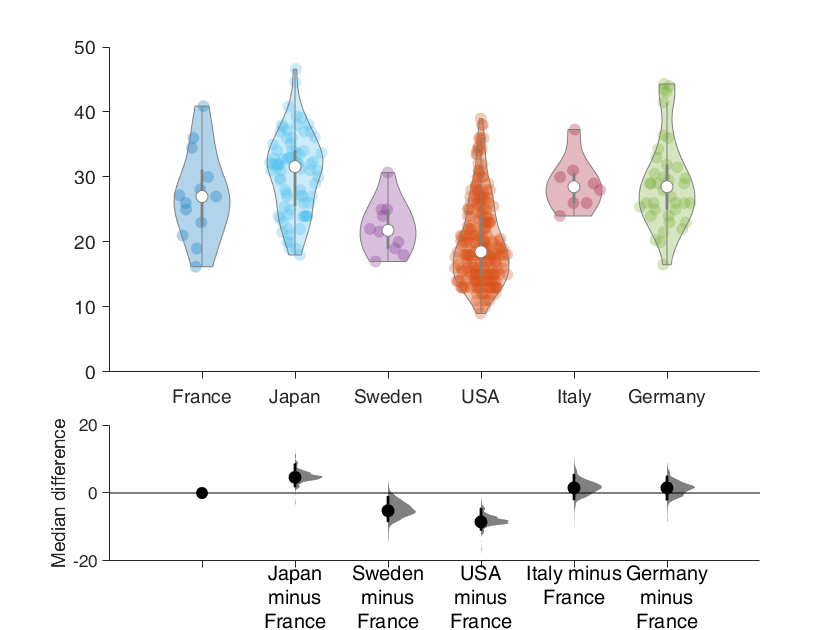

stats2 = 11×4 table
            Group             Value         CIs           N 
    ______________________    _____    ______________    ___

    'France'                    27        23    30.85     14
    'Japan'                   31.6      29.8     32.4     79
    'Sweden'                  21.8        19       25     11
    'USA'                     18.5        18     19.3    254
    'Italy'                   28.5        26       31      8
    'Germany'                 28.5        26     29.9     39
    'Japan minus France'       4.6       1.4      9.1    NaN
    'Sweden minus France'     -5.2     -9.35        0    NaN
    'USA minus France'        -8.5     -11.8       -4    NaN
    'Italy minus France'       1.5      -3.1      6.5    NaN
    'Germany minus France'     1.5     -3.25        6    NaN


h = struct with fields:
    fig: [1×1 Figure]
    ax1: [1×1 Axes]
     v1: [1×6 Violin]
    ax2: [1×1 Axes]
     v2: [1×6 DabestViolin]


figure
%grouporder specifies what everything is referenced against so important
grouporder={'France','Japan','Sweden', 'USA','Italy','Germany'};
[stats2 h]=violinplusdabest(MPG2, Origin2,grouporder)